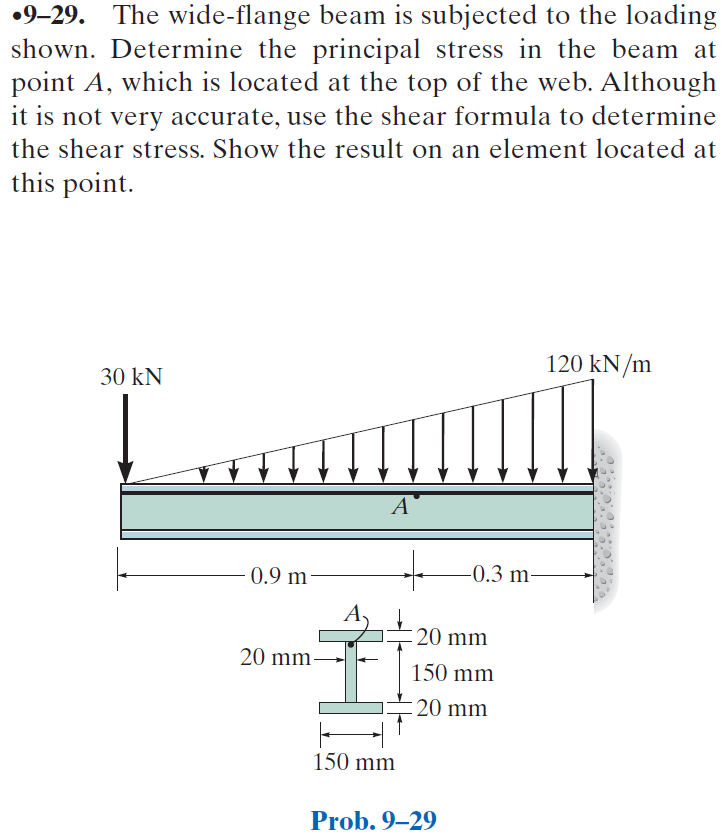

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-29P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-29P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

w1 = findpoly(1, 'thru', [0 0], 'thru', [1.2*u.m -120*u.kN/u.m]);

# beam

b = beam;
b = b.add('concentrated', 'force', -30*u.kN, 0);
b = b.add('reaction', 'force', 'R', 1.2*u.m);
b = b.add('reaction', 'moment', 'M', 1.2*u.m);
b = b.add('distributed', 'force', w1, [0 1.2]*u.m);
b.L = 1.2*u.m;

# section properties

yc = [150/2+20/2; 0; -150/2-20/2]*u.mm;
Ac = [150*20; 20*150; 150*20]*u.mm^2;
Ic = [150*20^3; 20*150^3; 150*20^3]/sym(12)*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = -\frac{32000\,{\left(5\,x-6\,m\right)}^{2}\,\left(125\,x^{3}+300\,x^{2}\,m+1290\,x\,m^{2}+2664\,m^{3}\right)}{5901\,\text{E}}\,\frac{\mathrm{kN}}{m^{6}}$$

dy

$$dy(x) = -\frac{800000\,\left(25\,x^{2}+126\,m^{2}\right)\,\left(5\,x-6\,m\right)\,\left(5\,x+6\,m\right)}{5901\,\text{E}}\,\frac{\mathrm{kN}}{m^{6}}$$

m

$$m(x) = -\frac{10\,x\,\left(5\,x^{2}+9\,m^{2}\right)}{3}\,\frac{\mathrm{kN}}{m^{2}}$$

v

$$v(x) = -10\,\left(5\,x^{2}+3\,m^{2}\right)\,\frac{\mathrm{kN}}{m^{2}}$$

w

$$w(x) = -100\,x\,\frac{\mathrm{kN}}{m^{2}}$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} M & -64.8\,\mathrm{kN}\,m\\ R & 102.0\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

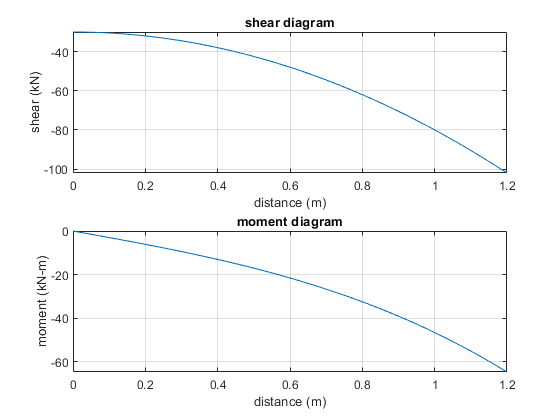

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# loads at point A

M = m(0.9*u.m);
M_vpa = vpa(M) %#ok<NASGU> 

$$M\_vpa = -39.15\,\mathrm{kN}\,m$$

V = v(0.9*u.m);
V_vpa = vpa(V) %#ok<NASGU> 

$$V\_vpa = -70.5\,\mathrm{kN}$$

# stresses at point A

% --------------
% bending stress
% --------------
Y = 150*u.mm/2;
b.I = rewrite(b.I, u.mm);
sigma_bending = rewrite(-M*Y/b.I, u.MPa);
sigma_bending_vpa = vpa(sigma_bending, 4) %#ok<NASGU> 

$$sigma\_bending\_vpa = 59.71\,\mathrm{MPa}$$

% ------------
% shear stress
% ------------
Q = Qn(1);
t = 20*u.mm;
tau_shear = rewrite(-V*Q/(b.I*t), u.MPa);
tau_shear_vpa = vpa(tau_shear, 4) %#ok<NASGU> 

$$tau\_shear\_vpa = 18.28\,\mathrm{MPa}$$

# mohr stresses at point A

sigmax = sigma_bending;
sigmax_vpa = vpa(sigmax, 4) %#ok<NASGU> 

$$sigmax\_vpa = 59.71\,\mathrm{MPa}$$

sigmay = sym(0)

$$sigmay = 0$$

tauxy = tau_shear;
tauxy_vpa = vpa(tauxy, 4) %#ok<NASGU> 

$$tauxy\_vpa = 18.28\,\mathrm{MPa}$$

[sigmaxp sigmayp tauxyp thetap] = beam.principal(sigmax, sigmay, tauxy);
[sigmaxs sigmays tauxys thetas] = beam.max_shear(sigmax, sigmay, tauxy);

# mohr's circle for point A

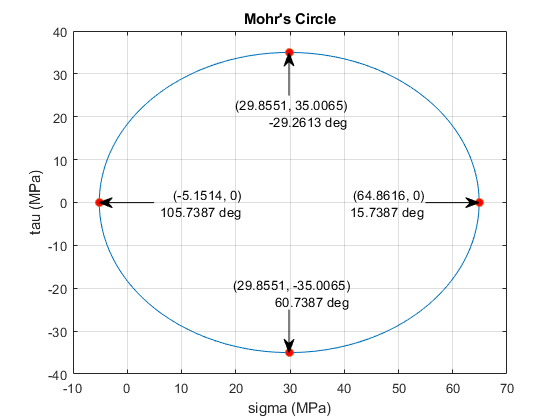

beam.mohr_plot(sigmax, sigmay, tauxy, {'MPa'});
axis([-10 70 -40 40]);
xvals = double(separateUnits([sigmaxp sigmaxs]));
yvals = double(separateUnits([tauxyp tauxys]));
thetavals = double(separateUnits([thetap thetas]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = 55;
      y1 = 0;
    case 2
      x1 = 5;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = 25;
    case 4
      x1 = xvals(4);
      y1 = -25;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear M_vpa V_vpa;
clear sigma_bending_vpa tau_shear_vpa;
clear sigmax_vpa tauxy_vpa;
clear xvals yvals thetavals k x1 y1 x2 y2 text_str;